# Student Exercise 1: Analyzing Malus's Law

In example (1) we explained the process of fitting your model onto data using the least squared method. Now we'll be taking into account the error associated with our data. The example data set we will be using is *malus3.txt, *which describes the periodic nature of polarized light. Malus's law states that the overall intensity of a linearly polarized light source is proportional to the square of the angle between the polarization axis and the analyser,

Malus's Law:  $I(\theta) \propto \text{cos}^2(\theta)$

## Read In Raw Data:

First create a path to the data folder,

%Fill in code here                   

Split the data into individual vectors for $x
$ and $y$ values and now we're going to include errors on $y$; $\sigma_y$

%Fill in code here                   

Sort the $x
$ and $y$ vectors in order of x_data. This ensures our data goes up in positive vaues in the $x
$ axsis

%Fill in code here                   

Let's plot the Raw data to seethe gaussian shape of the dataset.

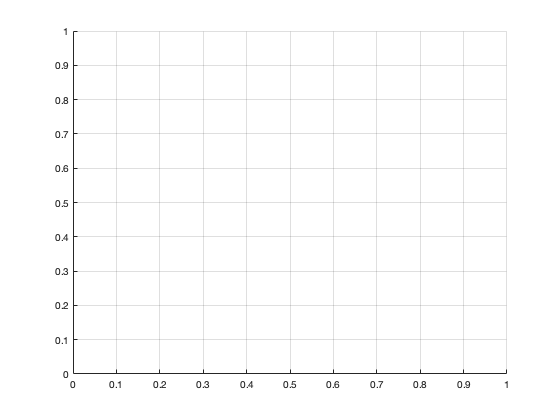

fig1 = figure;
ax1 = axes(fig1);
hold on
grid on

%Fill in code here                   

## $\chi^2$-Fitting and Error Analysis:

MATLAB's $\chi^2 $-fitting function is the same as it's least squared function *fit()* . In this case we feed it a additional paramter, the 'weight'. The weight is defined as $w = 1/\sigma^2$. The reason being that this is the factor that appends to the original LS method. Instead of using a generic model fit type found in [https://www.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl.](https://www.mathworks.com/help/curvefit/list-of-library-models-for-curve-and-surface-fitting.html#btbcvnl.) we're going to construct a fit model using the *fittype() *function for the generic melus's law equation mentioned in the introduction,


$$f(x| a_{1}, a_{2}, a_{3}, a_{4}) =a_{1} \cdot\text{sin}^2(a_{2}\cdot x + a_{3}) + a_{4}$$


Here $a_1$ encodes the amplitude, $a_2$ encodes the frequency information, $a_3$ encodes the phase shift, and $a_4$ encodes the DC shift. Keep in mind that the MATLAB doesn't understand the underlying physics and is only concerned with numerical computations (This isn't true with symbolic languages). With that in mind, we should keep track of the units on each parameter. Since $f(x)$ has units of $[W/m^2]$ then, ($a_1$, $a_2$, $a_3$, $a_4$) have units of ($[W/m^2]$, $[\text{rads}/\text{cm}]$,$[\text{rads}]$,$[W/m^2]$) respectivly. Setting up the fit type object,

%ft = fittype();  Fill in the fit type with the model

Next, call the *fit() *function with the data, errors and fittype. Once the weights are given to the function it will return more than the ordinary fit object shown in example.1. This time it'll output an array of objects we'll call [*f, gof, fit_output*]. The first, '*f', *is the same object from LS fitting which carries the fittype model and fit paramters. We will discuss the others in the next section.  

%[f, gof, fit_output] = fit();  Fill in the parameters for the fit function

Finding the errors on the parameters requires a extra statistics and some linear algebra. Within the *fit_ouput *object matlab calculates the weighted Jocobian matrix $J$. This mathematical object facilates the transformations of our parameter coordinate system into the new minimized system (you don't have to worry about understanding the gritty details if this is outside the scope of your statistics knowlegde). We care about this object because it allows us to calculate the covariance matrix $\epsilon_{ij}$, which encodes the various uncertainties of our parameters. The covariance is defined as, 


$$\epsilon_{ij} = \frac{1}{2}\bigg(\frac{\partial \chi}{\partial a_{i} \partial a_{j}}\bigg)^{-1}  = (J^{T}J)^{-1}$$
 

The last line is the inverse of the product of the jocobian matrix with it's transpose and can easily be done with using the following expression,

%extract the jocobian matrix

Diagonals entries of the covariance matrix correspond to the variances (or the square of the standard deviation $\sigma^2$) of the parameters, starting in order of the defined paramters ($a_1$, $a_2$, $a_3$, $a_4$). Whereas the off-diagonal terms are the covariances between two parameters, i.e. the (2,1)-term is Cov($a_{2}$,$a_{1}$). 

Let's see visually inspect the goodness of fit by plotting the fitted function with the found parameters over the raw data. Later we can use more robust quantatative methods of goodness of fit with the remaining objects returned from *fit(). *First let's generate an array of x values that spans the x range of our data using *linspace() *as well as construct the melus law model fucntion

% fill with code

Ploting the function over the already created (and held) figure objects.

% fill with code

## Goodness-of-fit and P-value:

Visually the model seems to fit well over our data. Although, these types of visual inspections can a dangerous form of inference because we'll show quantatively that the model doesn't fit our data well at all (within 2$\sigma$ signifigance). In the process of figuring out why involves getting to the heart of the name $\chi^2$. The parameters we just found are taken at the minimum value of the $\chi^2$ function, which we call $\chi^2_{\text{min}}$. If we were to redo the experiment the recalculated $\chi^2_{\text{min}}$ values should follow the $\chi^2$distribution, hence the name, 


$$f(x|\nu) = \frac{1}{2^{2/\nu}\Gamma(\nu/2)}x^{\nu/2-1}e^{-x/2}$$


Where $\nu$ is the number of degrees of freedom, which is the number of data points - the number of model parameter,


$$\nu = \text{(no. data  points) - (no. params) = } 100 - 4 = 96$$


We can either brute force calculate $\chi^2_{\text{min}}$ using the $\chi^2$ function and our data or we can use the value already calculated in the *gof output.*

% Find min chi squared

Both methods prove to give the same result. It'll be easier to use the *gof.sse *value for future analysis. We are now in a position to ask: *"what is the probability, if our hypothesis is correct, of getting a *$\chi^2_{\text{min}}$* value greater than or equal to the one that we got?". *The answer is the p-value, and is given by, 


$$p = \int^{\infty}_{\chi^2_{\text{min}}} f(x|\nu) dx$$


This basically represents the integral of the remaining (one sided) tail $f(x|\nu)$. We can check if our p-value less than some selected signifigance, usually taken to be 0.5 ($2\sigma$ signifigance). If p < 0.05, then we reject the hypothesis that our chosen model is the correct model. Otherwise, we fail to reject the hypothesis (that’s the strongest thing we can say; we are unable to conclude that the hypothesis is the correct one). But getting a large p-value (i.e. > 0.95) is also non-ideal. It means that we are overfitting the data (i.e. too many parameters in the fit model) or that our measurement uncertainties are overestimated. On average, we expect the p-value to be about 0.5 if the hypothesis is correct.

Alternatively, the chi-squared distribution has an expectation value of 𝜈, so if our calculated $\chi^2_{\text{min}}$ ≈ 𝜈, then we say the fit is ‘good’. Using this logic we it is customary to define $\chi^{2}_{\nu} =\chi^2/\nu $, the reduced chi-squared statistic. Based on the above, for a ‘good’ fit it should be about equal to 1. Typically it is more informative to report the p-value, the $\chi^2_{\text{min}}$ and 𝜈, rather than simply reporting the value of $\chi^{2}_{\nu}$.  

MATLAB has cumulative distribution function calculator, we can use this to find the p-value and interpret our results.

% calculate the corresponding p-value and reduced chi squared

Question #1: Is this a good fit? What can we say from the p-value measured?

Answer #1:

Question #2: How would this result change if we included more (or less) parameters in our model?

Answer #2: